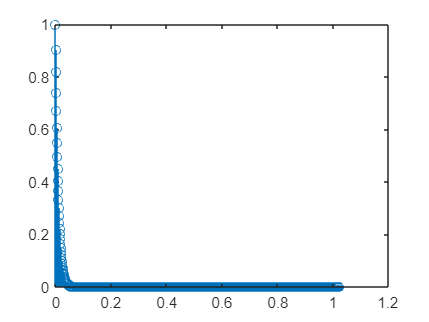

%Lab 5 9/29/2023 Lisa Jacklin

%starting on slide 2
fs = 1000; %sampling frequency
ts = 1/fs; %sampling time
N = 1024; %sample size
t = 0:ts:(N-1)*ts; %this will give us how many samples we are looking for

%time domain
xn = exp(-100*t);
stem(t, xn);

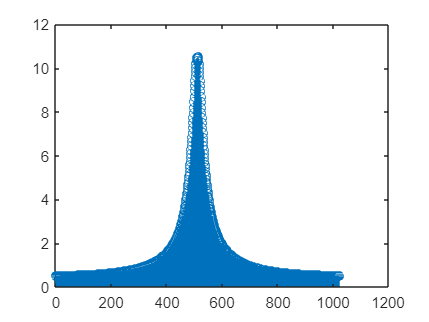

%frequency domain
xw = fftshift(fft(xn));
stem(abs(xw));

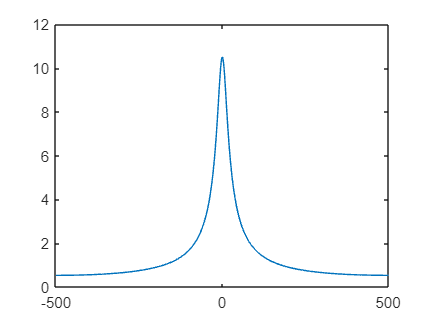


F = -fs/2: fs/(N-1):fs/2;
plot(F, abs(xw)); %this range of F gives us the frequency range

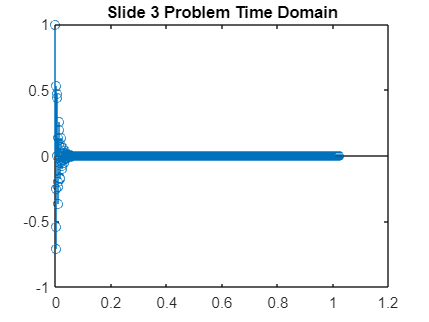

%now running problem on slide 3
fs = 1000;
ts = 1/fs;
N = 1024;
t = 0:ts:(N-1)*ts;

%first i'm plotting in the time domain to check items
yn = exp(-100*t) .* cos(2*pi*150*t);
stem(t, yn);
title("Slide 3 Problem Time Domain");

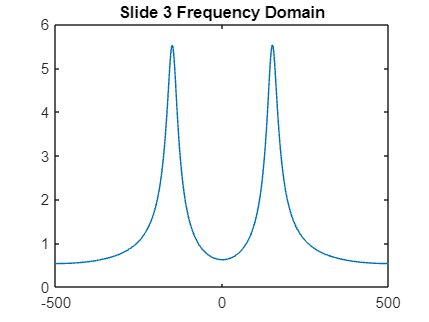


%now I'm plotting in the frequency domain
yw = fftshift(fft(yn));
F = -fs/2:fs/(N-1):fs/2;
plot(F, abs(yw));
title("Slide 3 Frequency Domain")

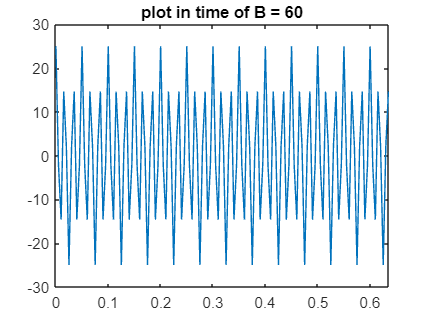

%now working on the problem on slide 4
fs= 200;
ts = 1/fs;
N = 128;
t = 0:ts:(N-1)*ts;

%time domain for the three signals
xn1 = 5*cos(2*pi*20*t) + 20*cos(2*pi*60*t);
xn2 = 5*cos(2*pi*20*t) + 20*cos(2*pi*70*t);
xn3 = 5*cos(2*pi*20*t) + 20*cos(2*pi*80*t);

plot(t, xn1); title("plot in time of B = 60");

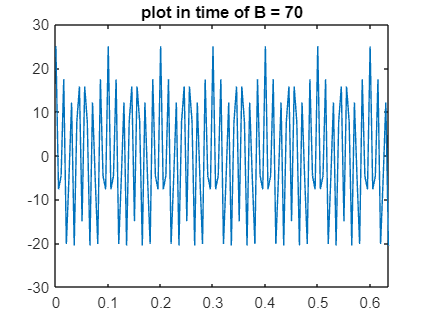

plot(t, xn2); title( "plot in time of B = 70");

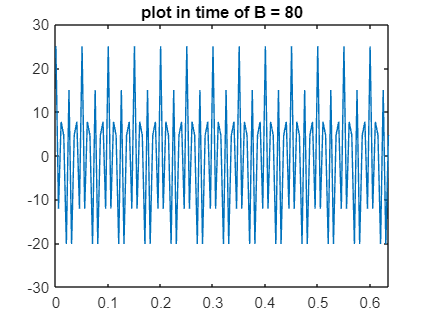

plot (t, xn3); title("plot in time of B = 80");

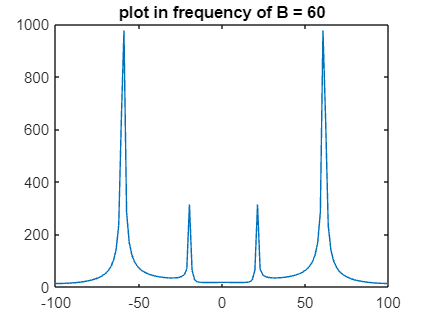

%frequency domain for the three signals...
xw1 = fftshift(fft(xn1));
xw2 = fftshift(fft(xn2));
xw3 = fftshift(fft(xn3));
F = -fs/2:fs/(N-1):fs/2;
plot(F, abs(xw1)); title("plot in frequency of B = 60");

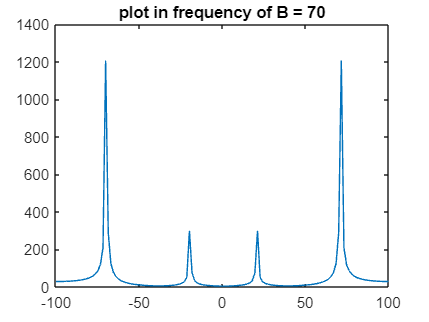

plot(F, abs(xw2)); title("plot in frequency of B = 70");

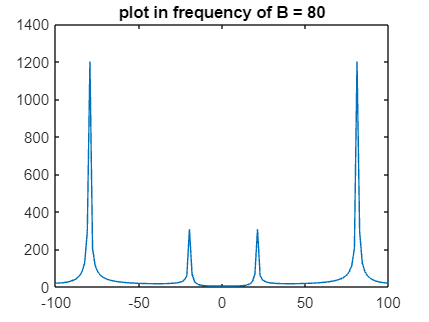

plot(F, abs(xw3)); title("plot in frequency of B = 80");

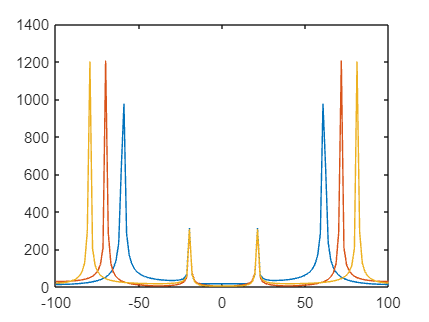


%because fancy and comparisons!
plot(F, abs(xw1), F, abs(xw2), F, abs(xw3));